Utilizando el RST

Construimos el robot, se definen las longitudes y la matriz de parametros mdh 

clear
robot = rigidBodyTree;
L1=5; L2=5; L3=30; L4=5; L5=45; L6=5; L7=5; L8=10;
dhparams = [0    0    L1    0;
       0    pi/2 L2    0;
       L3   0    0     0;
       L5   0   -L4-L6 0;
       pi/2 0    L7    pi/2;
       pi/2 0    L8    0;];

Creamos los eslabones, los joints y se transforma explicitamnte solicitando la configuración "mdh" 

body1 = rigidBody('body1'); 
jnt1 = rigidBodyJoint('jnt1','revolute');
setFixedTransform(jnt1,dhparams(1,:),'mdh');
body1.Joint = jnt1;
addBody(robot,body1,'base')

body2 = rigidBody('body2'); 
jnt2 = rigidBodyJoint('jnt2','revolute');
body3 = rigidBody('body3'); 
jnt3 = rigidBodyJoint('jnt3','revolute');
body4 = rigidBody('body4'); 
jnt4 = rigidBodyJoint('jnt4','revolute');
body5 = rigidBody('body5'); 
jnt5 = rigidBodyJoint('jnt5','revolute');
body6 = rigidBody('body6'); 
jnt6 = rigidBodyJoint('jnt6','revolute');


Se definen las relaciones de cada eslabón y se ensambla, ademas se meustran los detalles de el tipo de joint, el padre y el hijo de cada uno :

setFixedTransform(jnt2,dhparams(2,:),'mdh');
setFixedTransform(jnt3,dhparams(3,:),'mdh');
setFixedTransform(jnt4,dhparams(4,:),'mdh');
setFixedTransform(jnt5,dhparams(5,:),'mdh');
setFixedTransform(jnt6,dhparams(6,:),'mdh');
body2.Joint = jnt2;
body3.Joint = jnt3;
body4.Joint = jnt4;
body5.Joint = jnt5;
body6.Joint = jnt6;

addBody(robot,body2,'body1')
addBody(robot,body3,'body2')
addBody(robot,body4,'body3')
addBody(robot,body5,'body4')
addBody(robot,body6,'body5')
%showdetails(robot)

Se muestra el robót :

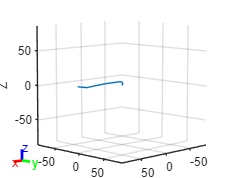

ans =   Axes (Primary) with properties:

             XLim: [-86 86]
             YLim: [-86 86]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


show(robot)

%viztree = interactiveRigidBodyTree(robot)
showdetails(robot)

--------------------
Robot: (6 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   body3(3)  
   3        body3         jnt3     revolute            body2(2)   body4(4)  
   4        body4         jnt4     revolute            body3(3)   body5(5)  
   5        body5         jnt5     revolute            body4(4)   body6(6)  
   6        body6         jnt6     revolute            body5(5)   
--------------------


Teach